
clear; close all; clc;

%% Zadoff-Chu Preamble Schmidl formatında
N = 64;
root = 29;
n = 0:N-1;
X = exp(-1j * pi * root * n.^2 / N);
preamble = [X, X]'; 



%% Preamble ortada
data_before = 0.3 * (randn(100, 1) + 1j * randn(100, 1));  
data_after = 0.3 * (randn(100, 1) + 1j * randn(100, 1)); 

tx_signal = [data_before; preamble; data_after];  % Preamble ortada
rx_signal = awgn(tx_signal, 30, 'measured'); 

%% Schmidl Algoritması
L = N;  % yarım preamble
P = zeros(length(rx_signal), 1);
R = zeros(length(rx_signal), 1);
M = zeros(length(rx_signal), 1);

for n = 1:length(rx_signal) - (2*L - 1)
    P(n) = sum(conj(rx_signal(n:n+L-1)) .* rx_signal(n+L:n+2*L-1));
    R(n) = sum(abs(rx_signal(n+L:n+2*L-1)).^2);
    M(n) = abs(P(n))^2 / (R(n)^2 + eps);
end

%% Pik Noktasını Bulma
[peak_value, peak_index] = max(M);
preamble_start = peak_index;  

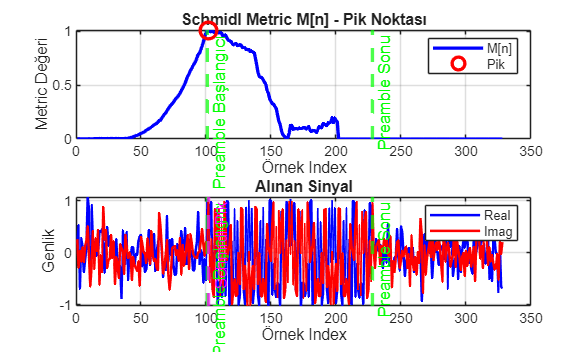


figure;

subplot(2,1,1);
plot(M, 'b', 'LineWidth', 2);
hold on;
plot(peak_index, peak_value, 'ro', 'MarkerSize', 10, 'LineWidth', 2);
xline(length(data_before) + 1, 'g--', 'LineWidth', 2, 'Label', 'Preamble Başlangıcı');
xline(length(data_before) + length(preamble), 'g--', 'LineWidth', 2, 'Label', 'Preamble Sonu');
title('Schmidl Metric M[n] - Pik Noktası');
xlabel('Örnek Index');
ylabel('Metric Değeri');
legend('M[n]', 'Pik');
grid on;


subplot(2,1,2);
plot(real(rx_signal), 'b', 'LineWidth', 1.5);
hold on;
plot(imag(rx_signal), 'r', 'LineWidth', 1.5);
xline(length(data_before) + 1, 'g--', 'LineWidth', 2, 'Label', 'Preamble Başlangıcı');
xline(length(data_before) + length(preamble), 'g--', 'LineWidth', 2, 'Label', 'Preamble Sonu');
xline(peak_index, 'm--', 'LineWidth', 2, 'Label', 'Schmidl Pik');
title('Alınan Sinyal');
xlabel('Örnek Index');
ylabel('Genlik');
legend('Real', 'Imag');
grid on;


fprintf('Gerçek Preamble Başlangıcı: %d\n', length(data_before) + 1);

Gerçek Preamble Başlangıcı: 101


fprintf('Gerçek Preamble Sonu: %d\n', length(data_before) + length(preamble));

Gerçek Preamble Sonu: 228


fprintf('Schmidl Pik Indexi: %d\n', peak_index);

Schmidl Pik Indexi: 102


fprintf('Pik Değeri: %.4f\n', peak_value);

Pik Değeri: 1.0126



% Schmidl algoritmasına göre pik, preamble'in başında çıkar
expected_peak = length(data_before) + L + 1; 
fprintf('Beklenen Pik (Preamble Ortası): %d\n', expected_peak);

Beklenen Pik (Preamble Ortası): 165


fprintf('Hata: %d örnek\n', abs(peak_index - expected_peak)); 

Hata: 63 örnek
